# Simulation of PID Computed-Torque Control

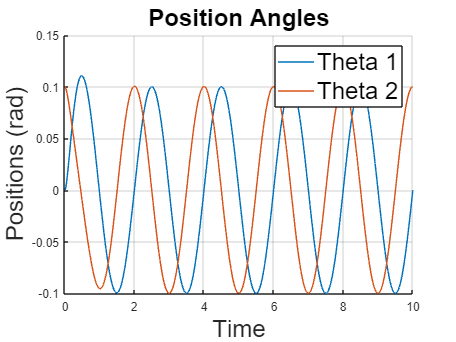

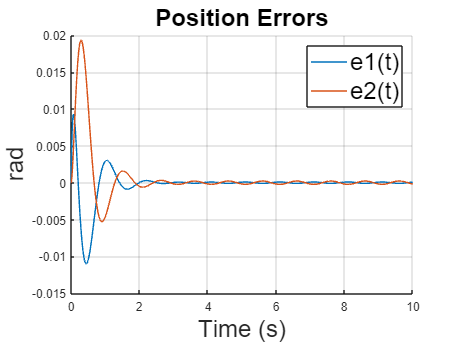

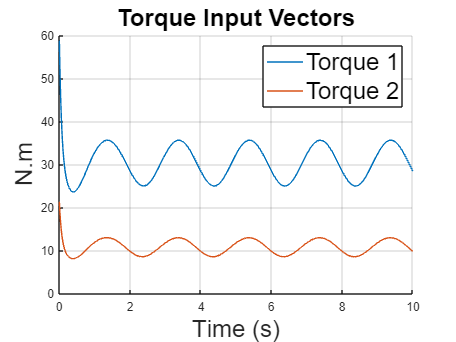

clc; clear;


% ODE solver
[t,x]= ode45(@(t,x) RoboticArm(t,x), [0 10], [0 0.1 0 0 0 0]); % intial values
figure
hold on;
plot(t,x(:,1:2))
legend("Theta 1","Theta 2","FontSize",20);
title("Position Angles","FontSize",20);
xlabel("Time","FontSize",20);
ylabel("Positions (rad)","FontSize",20);
grid on;


Qd = zeros(n,2);
% desired q (theta 1  and theta 2) calculation for every second
for i=1:n 
[qd, ~, ~] = desiredTrajectory(t(i)); 
Qd(i,:) = qd';
end

err = Qd- x(:,1:2); % position error
figure
hold on
plot(t,err);
xlabel('Time (s)','FontSize',20);
ylabel('rad','FontSize',20);
legend("e1(t)","e2(t)",'FontSize',20);
title("Position Errors",'FontSize',20);
grid on;

figure;
hold on;
u = zeros(n,2);
% Calculation of Torque inputs for every second
for i=1:n
[~,u(i,:)] = RoboticArm(t(i),x(i,:));
end
plot(t,u(:,1:2));
xlabel('Time (s)','FontSize',20);
ylabel('N.m','FontSize',20)
legend("Torque 1","Torque 2",'FontSize',20)
title('Torque Input Vectors','FontSize',20);
grid on;
%%

function [xdot,tau]=RoboticArm(t,x) 

theta1 = x(1);
theta2 = x(2);
theta1dot = x(3);
theta2dot = x(4);
ei = [x(5);
x(6)];

% Parameters of the Arm 
m1 = 1; m2 = 1; % mass
a1 = 1; a2 = 1; % arm length
g = 9.81; % gravity constant

% Inertia matrix M
M = [(m1+m2)*a1^2 + m2*a2^2 + 2*m2*a1*a2*cos(theta2),  m2*a2^2 + m2*a1*a2*cos(theta2);
     m2*a2^2 + m2*a1*a2*cos(theta2),                   m2*a2^2];


% Coriolis matrix N
N = [-m2*a1*a2*sin(theta2)*(2*theta1dot*theta2dot + theta2dot^2);
    m2*a1*a2*sin(theta2)*theta1dot^2];

% Gravity matris G
G = [(m1+m2)*g*a1*cos(theta1)+m2*g*a2*cos(theta1+theta2);
     m2*g*a2*cos(theta1 + theta2)];

% Constant Disturbance with 1 N.m in each component 
tau_d = [1;1];

% Control input
Kp = 100; Kv = 20; Ki = 500; % kp = wn^2 , kv= 2*wn
[qd, qd_dot, qd_ddot] = desiredTrajectory(t);

e = qd- [theta1; theta2]; % position error 
edot = qd_dot- [theta1dot; theta2dot]; % velocity error
tau = M*(qd_ddot + Kv*edot + Kp*e + Ki*ei) + N + G; % torque ( control input ) 

% Position/Velocity State Representation
xdot = [theta1dot;
theta2dot;
inv(M)*(-N-G-tau_d + tau);  % q double dot (acceleration ) we add tau-d here because the system is not assumed perfectly as in controller
e];                         % e = qd - qi
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [qd, qd_dot, qd_ddot] = desiredTrajectory(t) 
% Desired trajocteries are given by
% theta1 = amp * sin ( 2*pi*t / T ) 
%theta2 = amp * cos ( 2*pi*t/T ) 
T = 2; amp = 0.1; % period and amplitude
qd =[amp*sin(2*pi/T*t); % desired theta 1
    amp*cos(2*pi/T*t)]; % desired theta 2 

qd_dot =[amp*2*pi/T*cos(2*pi/T*t); % desired theta1 dot
        -amp*2*pi/T*sin(2*pi/T*t)]; % desired theta2 dot

qd_ddot =[-amp*2*pi/T*2*pi/T*sin(2*pi/T*t); % desired theta1 double dot
          -amp*2*pi/T*2*pi/T*cos(2*pi/T*t)]; % desired theta2 double dot
end
